## B Running HPC for LDE, then test LIF only

## 1. Setting up network

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures/Demo013022/'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/']; % V1
addpath(DataFolder)

### B1. Load LDE computations and do Fr distributions

%load("AllMFPixPara_Paper2TuneFig1V4D2.mat")
load("AllMFPixPara_Paper2TuneFig1V4.mat")
%load("AllMFPixPara_Paper2Tune.mat")
close all

if MF+v: omitting

If LIF-only: see coverage. Omitting

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
AngCtgr = 3; AngPrint = AngleList{AngCtgr};
Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5
L6up = 60; L6low = 6;
%load(sprintf('Paper2_LIFoLDE_Fig1V4D1_Ang%s_LGNc1_L6c1.mat',AngPrint))
load(sprintf('Paper2_LIFoLDE_Fig1V4D1_Ang%s_LGNc1_L6c1_L6_%d_%d_Cosine.mat',...
     AngPrint,L6up,L6low))
a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);
rowsmWin = 20; colswWin = 5;
MFv = false;
smth = true;
if MFv 
    LIFN = 5;
else
    LIFN = 3;
end

Load and make all 16 functions for this angle

LGNlist = 4; L6list = 4;
LDEFrVecS = zeros(length(L4ERcrd),LGNlist,L6list);
LDEFrVecC = zeros(length(L4ERcrd),LGNlist,L6list);
LDEFrVecI = zeros(length(L4ERcrd),LGNlist,L6list);

plotFlag = false;
%CtgrName = {'func1','func2','func3','func4','func5','func6','func7'};
for LGNCtgr = 1:LGNlist
    figure(LGNCtgr)
    for L6Ctgr = 1:L6list  
        %Ctgr = [LGNCtgr,L6Ctgr];
        %load(sprintf('Paper2_LIFoLDE_Fig1V4D1_Ang%s_LGNc%d_L6c%d.mat',...
        %                                           AngPrint,LGNCtgr,L6Ctgr))
        load(sprintf('Paper2_LIFoLDE_Fig1V4D1_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine.mat',...
                      AngPrint,LGNCtgr,L6Ctgr,L6up,L6low))
        L4EPlot = reshape(L4ERcrd,a2,a1);
        L4IPlot = reshape(L4IRcrd,a2,a1);
        FrLDE = zeros(length(f_EnIOut),LIFN);
        for LDEInd = 1:length(f_EnIOut)
            if ~(isempty(f_EnIOut{LDEInd}) || size(f_EnIOut{LDEInd},2)<25)
                FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,floor(end/2):end),2))';
            else
                FrLDE(LDEInd,:) = nan;
            end
        end
        FrLDE(FrLDE<0) = eps;
        % S rates
        subplot(L6list,3,(L6Ctgr-1)*3+1)
        LDEFrVecS(:,LGNCtgr,L6Ctgr) = ...
            LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
            LGNCtgr,L6Ctgr,'S',smth,plotFlag,MFv, [rowsmWin, colswWin] );
        
        % C rates
        subplot(L6list,3,(L6Ctgr-1)*3+2)
        LDEFrVecC(:,LGNCtgr,L6Ctgr) = ...
            LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
            LGNCtgr,L6Ctgr,'C',smth,plotFlag,MFv, [rowsmWin, colswWin] );
        
        % I rates
        subplot(L6list,3,(L6Ctgr-1)*3+3)
        LDEFrVecI(:,LGNCtgr,L6Ctgr) = ...
            LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
            LGNCtgr,L6Ctgr,'I',smth,plotFlag,MFv, [rowsmWin, colswWin] );
    end
end
close all

Create a function

L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400);
L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
[L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
% 2D function now, depending on input of total E and I kick numbers
for LGNCtgr = 1:LGNlist
    for L6Ctgr = 1:L6list
        LDEFrfunc.S{LGNCtgr,L6Ctgr} = ...
            griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY);
        LDEFrfunc.C{LGNCtgr,L6Ctgr} = ...
            griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY);
        LDEFrfunc.I{LGNCtgr,L6Ctgr} = ...
            griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY);
    end
end

## 3. Now Start Iteration

First, get an averaged Fr integration kernal

Write a function to smooth the integration kernel

New: Need to extend all these to arbitrary HC numbers!

N_HCOut = 3; PixNumOut = N_HCOut^2*NPixX*NPixY;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

Grating = Angle; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
% PhaseFRS_Grating = [45+abs(mod(GratingHC,180)-90)/2;
%                     45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;

FigOn = true;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;

L6smear = n_S_HC*0.30; LGNsmear = n_S_HC*0.05;
Trunc = 3;
L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,L6smear,Trunc,FigOn);
LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,LGNsmear,Trunc,FigOn);

PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
% Just note: This doesn't mean anything now...
PixInptCtgr = PixL6Ctgr*0.7 + PixLGNCtgr*0.3;
PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
for PixInd = 1:PixNumOut
    PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
end

Get pixelwise connectivities

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

Give an intial condition, Now start

try a dot product here

OPTPix = L6S_Pixel>0.93*max(L6S_Pixel); %   lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = L6S_Pixel<1.1*min(L6S_Drive);  %lambda_SOn_Pixel<0.22;
MeanFrCtry = @(x1) [mean(x1(OPTPix)),mean(x1(OBLPix)),...
                    mean(x1(ORTPix)),mean(x1(OBLPix))];
% MeanFrCtry1 = @(x1) [(mean(x1(OPTPix))*0.8+mean(x1(OBLPix))*0.2),...
%                      mean(x1(OBLPix)),...
%                      (mean(x1(ORTPix))*0.8+mean(x1(OBLPix))*0.2)];
LDEIni.S = PixInptCtgr * MeanFrCtry(FrSPixVec)';
LDEIni.C = PixInptCtgr * MeanFrCtry(FrCPixVec)';
LDEIni.I = PixInptCtgr * MeanFrCtry(FrIPixVec)';
for IndX = 9:20
    for IndY = 14:17
        PixInd = (IndX-1)*40 + IndY;
        LDEIni.C(PixInd) = 65;
    end
end

% LDEIni.S = ones(size(PixInptCtgr,1),1) * 2.47;
% LDEIni.C = ones(size(PixInptCtgr,1),1)  * 5.19;
% LDEIni.I = ones(size(PixInptCtgr,1),1)  * 14.36;

% LDEIni = LDEIniAll{5};

% LDEIni.S = ones(size(LDEIni.S))*mean(LDEIni.S,'all')*2/3;
% LDEIni.C = ones(size(LDEIni.C))*mean(LDEIni.C,'all')*2/3;
% LDEIni.I = ones(size(LDEIni.I))*mean(LDEIni.I,'all')*2/3;
% LDEIni.S = FrSPixVec;
% LDEIni.C = FrCPixVec;
% LDEIni.I = FrIPixVec;
figure('Name','LDE Initial')
subplot 231
ShowField(LDEIni.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
subplot 232
ShowField(LDEIni.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
subplot 233
ShowField(LDEIni.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
subplot 234
ShowField(FrSPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'S NW')
subplot 235
ShowField(FrCPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'C NW')
subplot 236
ShowField(FrIPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'I NW')
% Iteration
p = 0.2; % 1-p for the original input
Epoc = 30;
LDEItr = cell(Epoc+1,1);LDEItr{1} = LDEIni;
LDEEpoOut = cell(Epoc+1,1); LDEEpoOut{1} = LDEIni;

for Epc = 1:Epoc
    
    LDEUse = LDEItr{Epc};
    L4EUse = C_SS_mean*LDEUse.S + ...%- diag(C_SS_mean).*LDEUse.S + ...
             C_CS_mean*LDEUse.S + ...%- diag(C_CS_mean).*LDEUse.S + ...
             C_IS_mean*LDEUse.S + ...%- diag(C_IS_mean).*LDEUse.S + ...
             C_SC_mean*LDEUse.C + ...%- diag(C_SC_mean).*LDEUse.C + ...
             C_CC_mean*LDEUse.C + ...%- diag(C_CC_mean).*LDEUse.C + ...
             C_IC_mean*LDEUse.C  ;%- diag(C_IC_mean).*LDEUse.C ;
    L4IUse = C_SI_mean*LDEUse.I + ...%- diag(C_SI_mean).*LDEUse.I + ...
             C_CI_mean*LDEUse.I + ...%- diag(C_CI_mean).*LDEUse.I + ...
             C_II_mean*LDEUse.I  ;%- diag(C_II_mean).*LDEUse.I ;
    % See where does the input stands
    
    % Refer to functions
    LDEOut = struct('S',[],'C',[],'I',[]);
    LDEOut.S = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.S,...
        L4EUse,L4IUse,...
        PixInptCtgrUse);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.C = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.C,...
        L4EUse,L4IUse,...
        PixInptCtgrUse);
    % ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.I = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.I,...
        L4EUse,L4IUse,...
        PixInptCtgrUse);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDENext = struct(...
        'S',LDEOut.S*p + LDEUse.S*(1-p),...
        'C',LDEOut.C*p + LDEUse.C*(1-p),...
        'I',LDEOut.I*p + LDEUse.I*(1-p));
    LDEItr{Epc+1} = LDENext; LDEEpoOut{Epc+1} = LDEOut;
%     

end

One more fig for diff

% figure('Name','epoch diff')
% subplot 231
% Ep1 = 15; Ep2 = 17; Ep3 = 20;
% ShowField(LDEEpoOut{Ep1}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep1, Ep3))
% subplot 232
% ShowField(LDEEpoOut{Ep1}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep1, Ep3))
% subplot 233
% ShowField(LDEEpoOut{Ep1}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep1, Ep3))
% 
% subplot 234
% ShowField(LDEEpoOut{Ep2}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep2, Ep3))
% subplot 235
% ShowField(LDEEpoOut{Ep2}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep2, Ep3))
% subplot 236
% ShowField(LDEEpoOut{Ep2}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep2, Ep3))

h1 = figure('Name','LDE Iteration');
subplot 241
LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,LGNCtgr,L6Ctgr,'S',true,false);
hold on
scatter(L4EUse,L4IUse,'r.','Displayname','All Input');
view(2)
%     scatter(L4EUse(ORTPix),L4IUse(ORTPix),'r.','Displayname','ort');
%     scatter(L4EUse(OBLPix),L4IUse(OBLPix),'g.','Displayname','obl');
%     scatter(L4EUse(OPTPix),L4IUse(OPTPix),'b.','Displayname','opt');
%     scatter(L4EUse(ORTOBLBd_Pix),L4IUse(ORTOBLBd_Pix),'gd','Displayname','bd1');
%     scatter(L4EUse(OPTOBLBd_Pix),L4IUse(OPTOBLBd_Pix),'bx','Displayname','bd2');
legend('Location','southeast')
title(sprintf('Epoch = %d', Epc))
hold off
subplot 242
ShowField(LDEOut.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
subplot 243
ShowField(LDEOut.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
subplot 244
ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
subplot 246
ShowField(LDEEpoOut{Epc+1}.S - LDEEpoOut{Epc}.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S Diff')
subplot 247
ShowField(LDEEpoOut{Epc+1}.C - LDEEpoOut{Epc}.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C Diff')
subplot 248
ShowField(LDEEpoOut{Epc+1}.I - LDEEpoOut{Epc}.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I Diff')


h2 = figure('Name','EImap');
subplot 121
ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,...
    1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'E LDE')
subplot 122
ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
%saveas(h1,sprintf("%s16Func_Ang%s_SCI.fig",FigurePath,AngPrint))
%saveas(h2,sprintf("%s16Func_Ang%s_EI.fig",FigurePath,AngPrint))

 Compute Frs

% LDENames = fieldnames(LDEOut)
% for Nid = 1:length(LDENames)
%     CurrField = LDEOut.(LDENames{Nid});
%     CurrMap = reshape(CurrField,N_HCOut*NPixX,N_HCOut*NPixY);
%     CurrMapShrk = CurrMap(1:N_HC*NPixY,1:N_HC*NPixX);
%     LDEOutShrk.(LDENames{Nid}) = reshape(CurrMapShrk,N_HC*NPixY*N_HC*NPixX,1);
%     MeanFrCtry(LDEOutShrk.(LDENames{Nid}))
% end

## 3*. Just for checking Truncaction

N_HCOut = 3; PixNumOut = N_HCOut^2*NPixX*NPixY;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

Grating = Angle; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
% PhaseFRS_Grating = [45+abs(mod(GratingHC,180)-90)/2;
%                     45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;
%L6up = 60; L6low = 8; %[10 54; 12 50]
FL6_Angle1 = ((abs(mod(GratingHC,180)-90)/90)*(L6up-L6low)+L6low) /1e3;

FigOn = false;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;

L6smear = n_S_HC*0.30; LGNsmear = n_S_HC*0.10;

TruncList = 1:0.5:2.5; % of sigma
%h1 = figure(1);
h2 = figure(2); % setup the figure
FrCenters.S = zeros(8,length(TruncList)); % setup the center frs
FrCenters.C = zeros(8,length(TruncList));
for TruncInd = 1:length(TruncList)
Trunc = TruncList(TruncInd);
L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,L6smear,Trunc,FigOn);
LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,LGNsmear,1,FigOn);

PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
% Just note: This doesn't mean anything now...
PixInptCtgr = PixL6Ctgr*0.7 + PixLGNCtgr*0.3;
PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
for PixInd = 1:PixNumOut
    PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
end

Get pixelwise connectivities

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

Give an intial condition, Now start

try a dot product here

OPTPix = L6S_Pixel>0.93*max(L6S_Pixel); %   lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = L6S_Pixel<1.1*min(L6S_Drive);  %lambda_SOn_Pixel<0.22;
MeanFrCtry = @(x1) [mean(x1(OPTPix)),mean(x1(OBLPix)),...
                    mean(x1(ORTPix)),mean(x1(OBLPix))];
% MeanFrCtry1 = @(x1) [(mean(x1(OPTPix))*0.8+mean(x1(OBLPix))*0.2),...
%                      mean(x1(OBLPix)),...
%                      (mean(x1(ORTPix))*0.8+mean(x1(OBLPix))*0.2)];
LDEIni.S = PixInptCtgr * MeanFrCtry(FrSPixVec)';
LDEIni.C = PixInptCtgr * MeanFrCtry(FrCPixVec)';
LDEIni.I = PixInptCtgr * MeanFrCtry(FrIPixVec)';
for IndX = 9:20
    for IndY = 14:17
        PixInd = (IndX-1)*40 + IndY;
        LDEIni.C(PixInd) = 65;
    end
end
% Iteration
p = 0.2; % 1-p for the original input
Epoc = 30;
LDEItr = cell(Epoc+1,1);LDEItr{1} = LDEIni;
LDEEpoOut = cell(Epoc+1,1); LDEEpoOut{1} = LDEIni;

for Epc = 1:Epoc
    
    LDEUse = LDEItr{Epc};
    L4EUse = C_SS_mean*LDEUse.S + ...%- diag(C_SS_mean).*LDEUse.S + ...
             C_CS_mean*LDEUse.S + ...%- diag(C_CS_mean).*LDEUse.S + ...
             C_IS_mean*LDEUse.S + ...%- diag(C_IS_mean).*LDEUse.S + ...
             C_SC_mean*LDEUse.C + ...%- diag(C_SC_mean).*LDEUse.C + ...
             C_CC_mean*LDEUse.C + ...%- diag(C_CC_mean).*LDEUse.C + ...
             C_IC_mean*LDEUse.C  ;%- diag(C_IC_mean).*LDEUse.C ;
    L4IUse = C_SI_mean*LDEUse.I + ...%- diag(C_SI_mean).*LDEUse.I + ...
             C_CI_mean*LDEUse.I + ...%- diag(C_CI_mean).*LDEUse.I + ...
             C_II_mean*LDEUse.I  ;%- diag(C_II_mean).*LDEUse.I ;
    % See where does the input stands
    
    % Refer to functions
    LDEOut = struct('S',[],'C',[],'I',[]);
    LDEOut.S = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.S,...
        L4EUse,L4IUse,...
        PixInptCtgrUse);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.C = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.C,...
        L4EUse,L4IUse,...
        PixInptCtgrUse);
    % ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.I = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.I,...
        L4EUse,L4IUse,...
        PixInptCtgrUse);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDENext = struct(...
        'S',LDEOut.S*p + LDEUse.S*(1-p),...
        'C',LDEOut.C*p + LDEUse.C*(1-p),...
        'I',LDEOut.I*p + LDEUse.I*(1-p));
    LDEItr{Epc+1} = LDENext; LDEEpoOut{Epc+1} = LDEOut;
%    

end

One more fig for diff

% figure(2)
% subplot(3,length(TruncList),TruncInd)
% ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,...
%     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('E LDE\nTrunc=%.1fsigma',Trunc))
% caxis([6.3 27])
% subplot(3,length(TruncList),TruncInd+length(TruncList))
% ShowField(LDEOut.I,...
%     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('I LDE\nTrunc=%.1fsigma',Trunc))
% caxis([36 90])
% subplot(3,length(TruncList),TruncInd+length(TruncList)*2)
% ShowField(PixL6Ctgr*FL6_Angle1'*1e3,...
%     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('L6 \nTrunc=%.1fsigma',Trunc))
% caxis([6 60])

% figure(1)
% subplot(2,length(TruncList),TruncInd)
% ShowField(LDEOut.S,...
%     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S LDE\nTrunc=%.1fsigma',Trunc))
% 
% subplot(2,length(TruncList),TruncInd+length(TruncList))
% ShowField(LDEOut.C,...
%     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C LDE\nTrunc=%.1fsigma',Trunc))

print peak firing rates

fprintf('Truncation = %.1f sigma', Trunc)
fprintf('S Min = %.2f; S Max = %.2f',...
    min(LDEOut.S,[],'all'), max(LDEOut.S,[],'all'))
fprintf('C Min = %.2f; C Max = %.2f',...
    min(LDEOut.C,[],'all'), max(LDEOut.C,[],'all'))
fprintf('E Min = %.2f; E Max = %.2f',...
    min(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,[],'all'),...
    max(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,[],'all'))

Get center firing rates

% x0 = NPixX;  y0 = floor(NPixY*3/2);
% x45 = floor(NPixX*3/2); y45 = NPixY*2;
% x90 = NPixX*2; y90 = floor(NPixY*3/2); 
% x135 = floor(NPixX*3/2); y135 = NPixY;
% LDEOutS = reshape(LDEOut.S,N_HCOut*NPixY,N_HCOut*NPixX);
% LDEOutC = reshape(LDEOut.C,N_HCOut*NPixY,N_HCOut*NPixX);
% 
% FrCenters.S(1,TruncInd) = sum(LDEOutS(y0:y0+1,  x0:x0+1),  'all')/4;
% FrCenters.S(2,TruncInd) = sum(LDEOutS(y45:y45+1,x45:x45+1),'all')/4;
% FrCenters.S(3,TruncInd) = sum(LDEOutS(y90:y90+1,x90:x90+1),'all')/4;
% FrCenters.S(4,TruncInd) = sum(LDEOutS(y135:y135+1,x135:x135+1),'all')/4;
% 
% FrCenters.C(1,TruncInd) = sum(LDEOutC(y0:y0+1,  x0:x0+1),  'all')/4;
% FrCenters.C(2,TruncInd) = sum(LDEOutC(y45:y45+1,x45:x45+1),'all')/4;
% FrCenters.C(3,TruncInd) = sum(LDEOutC(y90:y90+1,x90:x90+1),'all')/4;
% FrCenters.C(4,TruncInd) = sum(LDEOutC(y135:y135+1,x135:x135+1),'all')/4;

For an arbitraty pixel in the center hypercolumn, get tuning curve data

requires a symmetry group!

LDEOutS = reshape(LDEOut.S,N_HCOut*NPixY,N_HCOut*NPixX);
LDEOutC = reshape(LDEOut.C,N_HCOut*NPixY,N_HCOut*NPixX);

%x0 = 13; y0 = 16; % make sure this is in the center HC, so x0, y0 \in [11,20]
x0 = 11; y0 = 19; % well, should use the other HC...
%x0 = 14; y0 = 20;
xC = NPixX*1.5+0.5; yC = NPixY*1.5+0.5;
xx = x0-xC; yy = y0-yC; % centered
RtPix = ...
    [xx,yy;
     yy,-xx;
     -xx,-yy;
     -yy,xx]; % rotational group
SmPix = ...
    [-yy,-xx;
     -xx,yy;
     yy,xx;
     xx,-yy]; % Symmetry group
PixAll = zeros(8,2);
PixAll(1:2:7,:) = RtPix; PixAll(2:2:8,:) = SmPix;
PixAllUse = floor(PixAll + repmat([xC,yC],8,1));
for PixInd = 1:8
    FrCenters.S(PixInd,TruncInd) = LDEOutS(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
    FrCenters.C(PixInd,TruncInd) = LDEOutC(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
end

save figure and data

end

Truncation = 1.0 sigma

S Min = 4.71; S Max = 13.73

C Min = 15.42; C Max = 56.52

E Min = 8.45; E Max = 26.64

Truncation = 1.5 sigma

S Min = 4.97; S Max = 13.61

C Min = 15.79; C Max = 54.64

E Min = 8.46; E Max = 25.85

Truncation = 2.0 sigma

S Min = 5.06; S Max = 13.24

C Min = 16.90; C Max = 52.41

E Min = 8.84; E Max = 24.99

Truncation = 2.5 sigma

S Min = 5.33; S Max = 13.14

C Min = 18.46; C Max = 51.26

E Min = 9.37; E Max = 24.67

save([DataFolder sprintf('FrPixX%dY%d_Ang%s.mat',x0,y0,AngPrint)],'FrCenters')
%saveas(h1,sprintf("%s16Func_Ang%s_SCI.fig",FigurePath,AngPrint))
% saveas(h2,sprintf("%s16Func_Ang%s_EI_L6_%d_%d_LGNsmear_Cosine.fig",...
%          FigurePath,AngPrint,L6low,L6up))

## 3*.1. Tuning curve

3 dim: 4 ODs, Truncations, 4 angles

Centers

% FrCentersAll.S = zeros(4,length(TruncList),length(AngleList));
% FrCentersAll.C = zeros(4,length(TruncList),length(AngleList));
% AngleAll = zeros(size(AngleList));
% for AngCtgr = 1: length(AngleList)
%     AngPrint = AngleList{AngCtgr};
%     AngleAll(AngCtgr) = str2num(AngPrint);
%     load([DataFolder sprintf('FrCenters_%s.mat',AngPrint)],'FrCenters')
%     FrCentersAll.S(:,:,AngCtgr) = FrCenters.S;
%     FrCentersAll.C(:,:,AngCtgr) = FrCenters.C;
% end
% TuningCurveTrunc.S = zeros(4*length(AngleList),length(TruncList));
% TuningCurveTrunc.C = zeros(4*length(AngleList),length(TruncList));
% for TruncInd = 1:length(TruncList)
%     FrData1Trunc.S = squeeze(FrCentersAll.S(:,TruncInd,:));
%     TuningCurveTrunc.S(                    1:length(AngleList),TruncInd) = ...
%         FrData1Trunc.S(1,:)';
%     TuningCurveTrunc.S(  length(AngleList)+1:2*length(AngleList),TruncInd) = ...
%         FrData1Trunc.S(2,end:-1:1)';
%     TuningCurveTrunc.S(2*length(AngleList)+1:3*length(AngleList),TruncInd) = ...
%         FrData1Trunc.S(4,:)';
%     TuningCurveTrunc.S(3*length(AngleList)+1:4*length(AngleList),TruncInd) = ...
%         FrData1Trunc.S(3,end:-1:1)';
%     
%     FrData1Trunc.C = squeeze(FrCentersAll.C(:,TruncInd,:));
%     TuningCurveTrunc.C(                    1:length(AngleList),TruncInd) = ...
%         FrData1Trunc.C(1,:)';
%     TuningCurveTrunc.C(  length(AngleList)+1:2*length(AngleList),TruncInd) = ...
%         FrData1Trunc.C(2,end:-1:1)';
%     TuningCurveTrunc.C(2*length(AngleList)+1:3*length(AngleList),TruncInd) = ...
%         FrData1Trunc.C(4,:)';
%     TuningCurveTrunc.C(3*length(AngleList)+1:4*length(AngleList),TruncInd) = ...
%         FrData1Trunc.C(3,end:-1:1)';
% end
% TuningCurveTrunc.S = [TuningCurveTrunc.S(end:-1:1,:);TuningCurveTrunc.S];
% TuningCurveTrunc.C = [TuningCurveTrunc.C(end:-1:1,:);TuningCurveTrunc.C];
% AnglePlot = AngleAll;
% for ODInd = 1:3
%     AnglePlot = [AnglePlot,AngleAll+(ODInd)*22.5];
% end
% AnglePlot = [-AnglePlot(end:-1:1),AnglePlot]

Any Pix

%x0 = 13; y0 = 16; % make sure this is in the center HC, so x0, y0 \in [11,20]
x0 = 11; y0 = 19;
%x0 = 14; y0 = 20;

FrPixsAll.S = zeros(8,length(TruncList),length(AngleList));
FrPixsAll.C = zeros(8,length(TruncList),length(AngleList));
AngleAll = zeros(size(AngleList));
for AngCtgr = 1: length(AngleList)
    AngPrint = AngleList{AngCtgr};
    AngleAll(AngCtgr) = str2num(AngPrint);
    load([DataFolder sprintf('FrPixX%dY%d_Ang%s.mat',x0,y0,AngPrint)],'FrCenters')
    FrPixsAll.S(:,:,AngCtgr) = FrCenters.S;
    FrPixsAll.C(:,:,AngCtgr) = FrCenters.C;
end

Get the tuning curves for different truncations

TuningCurveTrunc.S = zeros(8*length(AngleList),length(TruncList));
TuningCurveTrunc.C = zeros(8*length(AngleList),length(TruncList));
PixOrder = [1,2,7,4,5,6,3,8];% Group order of pixels
%PixOrder = 1:8;% Group order of pixels
for TruncInd = 1:length(TruncList)
    FrData1Trunc.S = squeeze(FrPixsAll.S(:,TruncInd,:));   
    FrData1Trunc.C = squeeze(FrPixsAll.C(:,TruncInd,:));
    
    for PixUseInd = 1:8
        PixU = PixOrder(PixUseInd);
        if mod(PixUseInd,2) == 1
           TuningCurveTrunc.C(...
               (PixUseInd-1)*length(AngleList)+1:PixUseInd*length(AngleList),...
               TruncInd) = FrData1Trunc.C(PixU,:)'; 
           TuningCurveTrunc.S(...
               (PixUseInd-1)*length(AngleList)+1:PixUseInd*length(AngleList),...
               TruncInd) = FrData1Trunc.S(PixU,:)'; 
        else
           TuningCurveTrunc.C(...
               (PixUseInd-1)*length(AngleList)+1:PixUseInd*length(AngleList),...
               TruncInd) = FrData1Trunc.C(PixU,end:-1:1)'; 
           TuningCurveTrunc.S(...
               (PixUseInd-1)*length(AngleList)+1:PixUseInd*length(AngleList),...
               TruncInd) = FrData1Trunc.S(PixU,end:-1:1)';  
        end
    end

end

AnglePlot = AngleAll;
for ODInd = 1:7
    AnglePlot = [AnglePlot,AngleAll+(ODInd)*22.5];
end

Plot tuning curves

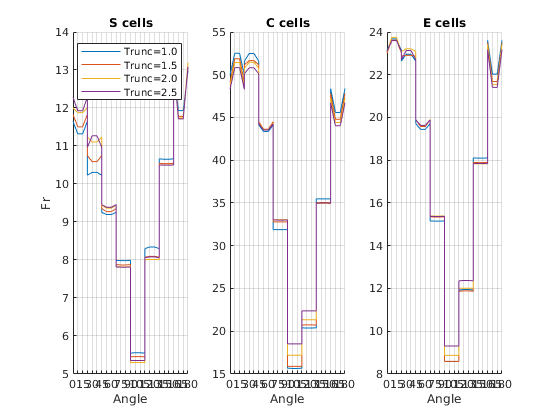

h3 = figure('Name','Tuning curve');
for TruncInd = 1:length(TruncList)
    subplot 131
    hold on
    plot(AnglePlot',TuningCurveTrunc.S(:,TruncInd),...
        'DisplayName',sprintf('Trunc=%.1f',TruncList(TruncInd)))
    xlabel('Angle'); ylabel('Fr'); title('S cells')
    
    subplot 132
    hold on
    plot(AnglePlot',TuningCurveTrunc.C(:,TruncInd),...
        'DisplayName',sprintf('Trunc=%.1f',TruncList(TruncInd)))
    xlabel('Angle'); title('C cells')
    
    subplot 133 
    hold on
    plot(AnglePlot',TuningCurveTrunc.S(:,TruncInd)*0.7 + ...
                    TuningCurveTrunc.C(:,TruncInd)*0.3,...
        'DisplayName',sprintf('Trunc=%.1f',TruncList(TruncInd)))
    xlabel('Angle'); title('E cells')
end
subplot 131
legend

xtickAng = unique(AnglePlot);
xtickLab = cell(size(xtickAng));
for xticInd = 1:length(xtickAng)
    if mod(xticInd,2) == 1
    xtickLab{xticInd} = num2str(xtickAng(xticInd));
    end
end

for PlotInd = 1:3
    subplot(1,3,PlotInd)
    set(gca,'xtick',unique(AnglePlot),'xticklabel',xtickLab)
    grid on
    xlim([min(xtickAng) max(xtickAng)])
end

saveas(h3,sprintf("%sTunCurve_PixX%d_Y%d.fig",FigurePath,x0,y0))